delta=zeros(1,1001);
delta(1)=1;
N=1000;
alpha=0.5;
B=[1,zeros(1,N-1),alpha];
he=filter(B,1,delta);

d=[1, zeros(1,4000)];
her=filter(1,[1, zeros(1,N-1),alpha],d);

nh = nhe(1) + nher(1) : nhe(end) + nher(end);
hoa = conv(he, her);

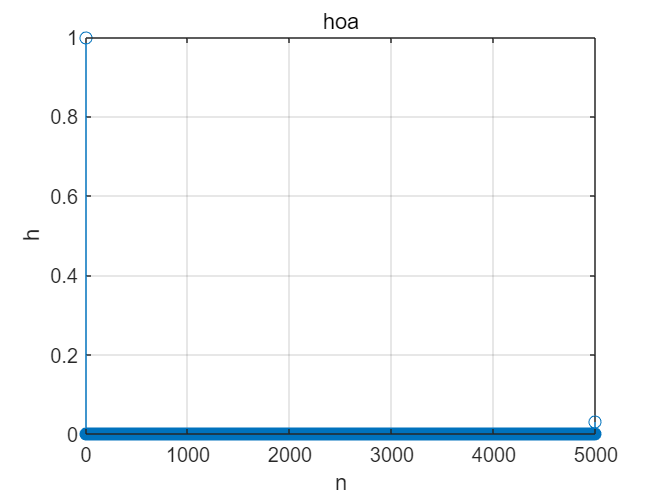

stem(nh, hoa);
title("hoa");
xlabel("n")
ylabel("h");
grid on;